clear;
clc;
close all;

addpath Datasets\cifar-10-batches-mat\

[X_train,Y_train,y_train] = LoadBatch('data_batch_1.mat');
[X_val, Y_val, y_val] = LoadBatch('data_batch_2.mat');
[X_test, Y_test, y_test] = LoadBatch('test_batch.mat');

n = size(X_train,2);
d = size(X_train, 1);
K = size(Y_train,1);

lambda = 0;
n_epochs = 40;
n_batch = 100; 
eta = .001;

[W, b] = GetParams(d, K);

%Check whether the gradient is correct or not
batch_size = 50;
eps =1e-10;

[ngrad_b, ngrad_W] = ComputeGradsNumSlow(X_train(:, 1 : batch_size), ...
    Y_train(:, 1 : batch_size), W, b, lambda, 1e-6);
P = EvaluateClassifier(X_train(:, 1 : batch_size),  W, b);
[grad_W, grad_b] = ComputeGradients(X_train(:, 1 : batch_size), ...
    Y_train(:, 1 : batch_size), P,  W, lambda);
%check gradients
gradcheck_b = max(abs(ngrad_b - grad_b));
gradcheck_W = max(abs(ngrad_W - grad_W));
if gradcheck_b <= 1e-6 
    fprintf("Correct grad_b");
else
    fprintf("Incorrect grad_b");
end

Correct grad_b

if gradcheck_W <= 1e-6 
    fprintf("Correct grad_W");
else
    fprintf("Incorrect grad_W");
end

Correct grad_W

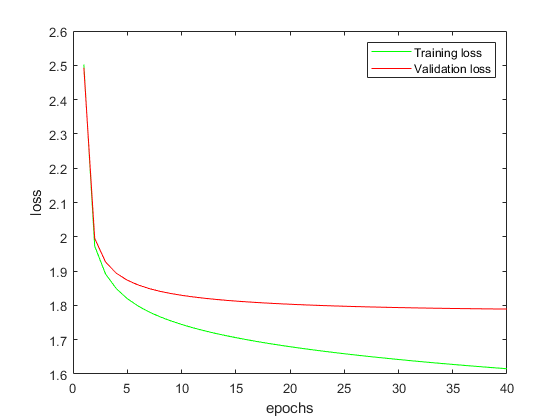

% %Preprocess raw input data on training set
mean_Xtr = mean(X_train, 2);
std_Xtr = std(X_train, 0 ,2);
% 
% % mean_Xva = mean(X_val, 2);
% % std_Xva = std(X_val, 0 ,2);
% % 
% % mean_Xte = mean(X_test, 2);
% % std_Xte = std(X_test, 0 ,2);
 %Normalize training validation and test data

X_train = X_train- repmat(mean_Xtr, [1, n]);
X_train = X_train./ repmat(std_Xtr, [1, n]);
 
X_val = X_val- repmat(mean_Xtr, [1, n]);
X_val = X_val./ repmat(std_Xtr, [1, n]);
 
X_test = X_test- repmat(mean_Xtr, [1, n]);
X_test = X_test./ repmat(std_Xtr, [1, n]);

% %eta_step = (eta-final_eta)/n_epochs;

cost_train = zeros(n_epochs, 1);
cost_eval = zeros(n_epochs, 1);

acc_test = zeros(n_epochs,1);
acc_train = zeros(n_epochs,1);

for i =1:n_epochs
    
    %DEBUGGING
    %Compute and store cost and accuracy for each epoch on all training set
    cost_train(i) = ComputeCost(X_train, Y_train, W, b, lambda);
    cost_eval(i) = ComputeCost(X_val, Y_val, W, b, lambda);
    
    acc_test(i) = ComputeAccuracy(X_test,y_test,W,b);
    acc_train(i) = ComputeAccuracy(X_train,y_train,W,b);
    
    for j = 1:n/n_batch
        j_start = (j-1)*n_batch + 1;
        j_end = j*n_batch;
        inds = j_start:j_end;
        Xbatch = X_train(:, j_start:j_end);
        Ybatch = Y_train(:, j_start:j_end);
        
        %Mini batch of X and Y
        [W, b] = MiniBatchGD(Xbatch,Ybatch,W,b,lambda,eta);
    end
end

%Plot cost scores
figure()
plot(1 : n_epochs, cost_train, 'g')
hold on
plot(1 : n_epochs, cost_eval, 'r')
hold off
xlabel('epochs');
ylabel('loss');
legend('Training loss', 'Validation loss');

% Accuracy of the network
acc_train_f = ComputeAccuracy(X_train, y_train, W, b);
disp(['Training Accuracy:' num2str(acc_train_f*100) '%'])

Training Accuracy:44.97%


acc_test_f = ComputeAccuracy(X_test, y_test, W, b);
disp(['Test Accuracy:' num2str(acc_test_f*100) '%'])

Test Accuracy:38.52%


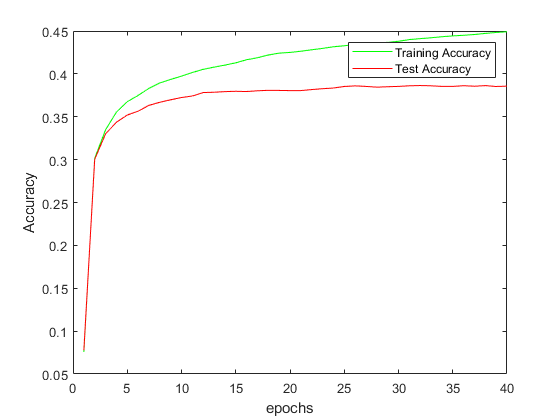

figure()
plot(1 : n_epochs, acc_train, 'g')
hold on
plot(1 : n_epochs, acc_test, 'r')
hold off
xlabel('epochs');
ylabel('Accuracy');
legend('Training Accuracy', 'Test Accuracy');

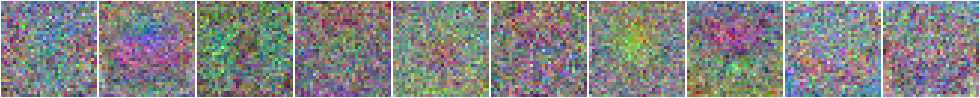


%Visualize the weight matrix W as an image and see what class template the
%network has learnt
K = 10;
for i = 1 : K
    im = reshape(W(i, :), 32, 32, 3);
    s_im{i} = (im - min(im(:))) / (max(im(:)) - min(im(:)));
    s_im{i} = permute(s_im{i}, [2, 1, 3]);
end
figure()
montage(s_im, 'size', [1, K]);

function [X,Y, y] = LoadBatch(file)
    %LOADBATCH reads in the data from a CIFAR-10 batch file
    %and returns the image and label data in separate files.
    A = load(file);
    X = double(A.data')/255;
    
    %label vector of size n
    y = A.labels';
    y = y + uint8(ones(1,length(y))); %Simplifying indexing
    
    %Create the image label matrix Y of size Kxn where K = #of labels.
    Y= zeros(10, length(y));
    for  i= 1:length(Y)
        Y(y(i),i) = 1;
    end
end

function P = EvaluateClassifier(X, W, b)
    %EVALUATECLASSIFIER that evaluates the network function, i.e. equations
    %(1, 2), on multiple images and returns the results.

    %Each column of X corresponds to an image and it has size dxn
    %W and b are the parameters of the network
    %Each column of P contains the probability for each label for the image 
    %in the corresponding column of X. P has size Kxn

    s = W*X + b;
    P = softmax(s);

end

function p = softmax(s)
    %Compute the softmax of S, return a probability vector
    p = exp(s)./sum(exp(s));
end

function [W,b] = GetParams(d , K)
    %GETPARAMS returns the initial parameters of the model (random guess))
    W = 0.01*randn(K, d); %0.01 is the standard deviation
    b = 0.01*randn(K, 1);
end

function J = ComputeCost(X,Y,W,b, lambda)
    %COMPUTECOST  computes the cost function given by equation
    %(5) for a set of images
    P = EvaluateClassifier(X,W,b);

    J= sum(diag(-log(Y'*P))/size(X,2) + lambda*sumsqr(W));
end

function acc = ComputeAccuracy(X, y, W, b)
    %COMPUTEACCURACY computes the accuracy of the network’s predictions given 
    %by equation (4) on a set of data.
    P = EvaluateClassifier(X,W,b);
    [~, pred] = max(P);
    acc = sum(pred == y)/length(P);
end

function [grad_W, grad_b] = ComputeGradients(X, Y, P, W, lambda)
%COMPUTEGRADIENTS evaluates, for a mini-batch, the gradients of the cost 
%function w.r.t. W and b, that is equations (10, 11). 
%X has size dxn
%Y has size Kxn
%P contains the probability for each label for the image in the
%corresponding column, has size Kxn

%grad_W is the gradient matrix of the cost J relative to W, has size 
%Kxd
%grad_b is the gradient vector of the cost J relative to b, has size 
%Kx1
    grad_W = zeros(size(W));
    grad_b = zeros(size(W, 1), 1);

    for i = 1 : size(X, 2)
        P_i = P(:, i);
        Y_i = Y(:, i);
        X_i = X(:, i);        
        
        g = -(Y_i-P_i)';
        grad_b = grad_b + g';
        grad_W = grad_W + g'*X_i';
 
    end
    % divide grad by the number of entries in D
    grad_b = grad_b/size(X, 2);
    grad_W = grad_W/size(X, 2) + 2*lambda*W ;
end

function [Wstar, bstar] = MiniBatchGD(X, Y, W, b, lambda, eta)
    P = EvaluateClassifier(X, W, b);
    [grad_W, grad_b] = ComputeGradients(X, Y, P, W, lambda);
    
    %Update parameters
    Wstar = W-eta*grad_W;
    bstar = b-eta*grad_b;
end
